# Optimization

## Learning Objectives

- Classify optimization problems as linear, quadratic, nonlinear, and mixed-integer problems.

- Learn how to interpret the solutions of optimization problems.

- Assess the sensitivity of a solution with respect to constraints.

- Learn how to formulate and solve optimization problems for multiple examples.

## Organization

- First, we'll review some of the types of optimization problems.

- You'll formulate and solve a simple nonlinear problem (wastewater treatment).

- Lastly, we'll analyze the nonlinear problem (wastewater treatment) from a sensitivity perspective

## Problem Forms

Optimizers generally exploit a specific mathematical structure in the problem formulation as a means to solve a problem. In fact, some  underlying assumptions are always required to ensure a problem is  optimized. One common example arrise from combining KKT conditions with  constraint qualifications or alternatively regularity conditions for  nonlinear programs.

These problem types range from linear programs for which problems with 100k variables and constraints may routinely be solved [in less than a minute](http://plato.asu.edu/ftp/lpsimp.html) to continuous convex problems to nonconvex nonlinear mixed-integer  problems (were some problems with fewer than 5 variables have yet to be solved). As such, using an appropriate optimizer for a particular  problem type can transform an unsolveable problem into a trival one. The most heavily studied and widely used descriptors for each program are  linear, quadratic, nonlinear, and mixed-integer.

### **Types of based on objectives/constraints:**

- **Linear:** All the constraints and the objective are linear.

- **Quadratic** all the constraints and the objective are quadratic or linear.

- **Nonlinear** at least one constraint or the objective is not linear.

### **Types based on manner of variable used:**

- **Continuous:** All variables can vary between values in some possibly open interval.

- **Integer:** All variables are integer valued.

- **Mixed-integer:** The problem contains both integer and continuous variables.

One of the central focuses of optimization research has focused on  developing specialized routines for solving programs with other special  forms. A number of other important forms include [specially-ordered sets](https://link.springer.com/article/10.1007/BF01589393), [second-order cones](https://ieeexplore.ieee.org/abstract/document/6983691), [equilibrium constraints](https://faculty.wcas.northwestern.edu/~lchrist/Ferris_mathematical_programs2.pdf), as well as a myriad of special nonlinear forms. When attempting to  solve a difficult model it's worth checking a few references (such as [Mosek's Modeling Cookbook](https://docs.mosek.com/MOSEKModelingCookbook-letter.pdf)) to see if the problem can be re-written as simplier form or a simplier problem type.

This trend has lead to the development of a number of specialized  languages and software packages used to describe optimization problems  interface with a myriad of different optimizers. In Python, the main  tools for this are [Pyomo](http://localhost:8888/notebooks/Desktop/Package%20Development/AnalysisNotebooks/tutorial/julia/Tutorial%206%20-%20Optimization/optimization_full.ipynb) and [CVXOPT](https://cvxopt.org/). In Julia, we have [JuMP](https://jump.dev/JuMP.jl/stable/), and [Convex.jl](https://jump.dev/Convex.jl/stable/). A number of other commercial offerings available include [GAMS](https://www.gams.com/), [AIMMS](https://en.wikipedia.org/wiki/AIMMS), and [AMPL](https://ampl.com/) along with a number of offerings associated with commercially available solvers such as [CPLEX Optimization Studio by IBM](https://www.ibm.com/analytics/cplex-optimizer) or [Xpress Mosel for FICO Express](https://www.fico.com/en/products/fico-xpress-optimization). 

## Integrating water system treatment in the process industry

*Adapted from *[*R. Karuppiah & I. Grossmann. Global optimization for the synthesis of  integrated water systems in chemical processes. Computers and Chemical  Engineering 30 (2006) 650–673*](https://www.sciencedirect.com/science/article/abs/pii/S0098135405002991)

The efficient utilitization of water will be an integral part to solving the numerous water management issues of today and the near future. Increasing usage of water, anticipated water scarities, and changing regulations are expected to result in numerous related challenges in the next  decades. These challenges may extend to the adaptation of numerous industrial processes. as fresh water is a key resource in such processes.  These include washing operations in the food processing, thermal processing (cooling, quenching, and scrubbing) in iron and steel  manufacturing, and the desalination of crude oil. In each of this  processes, some level of contamination is introduced into the freshwater by the process. This process water is then treated in a central  facility to remove contaminants and satisfy local regulatory specifications for the disposal of wastewater. In design or improvement of these central facilities, three key questions must be considered. 1) What unit operations need to be included? 2) How should these process units  be connected? 3) How should one operate these processes units?

A typical design objective for a wastewater treatment plant may be to minimize it's overall cost in a given year of operation. That is we minimize the sum of the cost fo freshwater intake, the investment cost associated with each treatment unit, and the operating cost of  each unit. This can be achieved by minimizing the follow objective:

                                                                    
$$\Phi =A_R \sum_j C_j^{Inv} F_j^{\alpha } +H\sum_j F_j C_j^{Op} +HF_{fw} C_{fw}$$


where H is the number of hours of operation per annum (*ℎ*); the cost of freshwater is given by $C_{fw}$ (`$/ton`); the fresh water intake mass if given by $F_{fw}$ (`ton/h`); The annualized factor for investment on treatment units is given by *𝐴𝑅*; the $C_j^{Inv} F_j^{\alpha }$ is the investment cost (`$`) of the *𝑗*-th treatment unit which treats a flowrate stream of contaminated water $F_j$ (`ton/h`); $C_j^{Op} F_j^{\alpha }$ is the operating cost (`$/h`) of the 𝑗-th treatment unit which treats a flowrate of contaminated water $F_j$ (`ton/h`); the parameter 𝛼 is a constant cost function exponent $0\le \textrm{𝛼}\le 1$.

The **mixers** units can be described as follows:

- The outlet flowrate is the sum of the inlet stream flow rate: $F^{outlet} =\sum_{i=1}^n F_i^{inlet}$ where $F^{outlet}$, $F_1^{inlet}$, $\dots$, $F_n^{inlet}$  are given in (tons/hr) and *𝑛 *is the number of inlets streams.

- The mass of each contaminant in the outlet equals the mass of each contaminant in the inlet streams: $F^{outlet} C_j^{outlet} =\sum_{i=1}^n F_i^{inlet} C_j^{inlet}$

The **splitter** units:

- The outlet flowrates are the sum of the inlet flowrate: $F^{inlet} =\sum_{i=1}^m F_i^{outlet}$ where $F^{inlet}$, $F_1^{outlet}$, …, $F_m^{outlet}$ are given in (tons/hr) and *𝑚 *is the number of outlet streams.

- The each outlet streams contaminant concentration is equal to the inlet stream contaminant concentration: $F_m^{outlet}$

A fixed mass of contaminant is added to a stream by each **process unit**:

- A process unit has a single inlet stream and a single outlet stream: $F^{inlet} =F^{outlet}$

- The process unit reduces the l $F^{inlet} C_j^{inlet} +L_j^p =F^{outlet} C_j^{outlet}$

The **treatment units**:

- A process unit has a single inlet stream and a single outlet stream with the same flowrate: $F^{inlet} =F^{outlet}$

- The concentration of contaminant in the outlet $C_j^{outlet} =\beta_j^t C_j^{inlet}$ where $\beta_j^t$ is the removal ratio of *𝑗*.

Two contaminants A & B are introduced into freshwater by a process and the concentration of each contaminant must be reduced to 10ppm prior to discharging it into the enviroment. The cost of freshwater is assumed to be $1/ton, the annualized factor for investment on the treatment unit is taken to be 0.1, and the total time of operation of the plant is 8000h/year. While numerous different treatment technologies and separation train configurations are possible, we've settled on using two distinct units to perform a primary and secondary treatment. We'd like to determine whether the inclusion of a recycle stream(s) may reduce the process cost and whether is preferable to have the recyle stream bridge one unit or two.

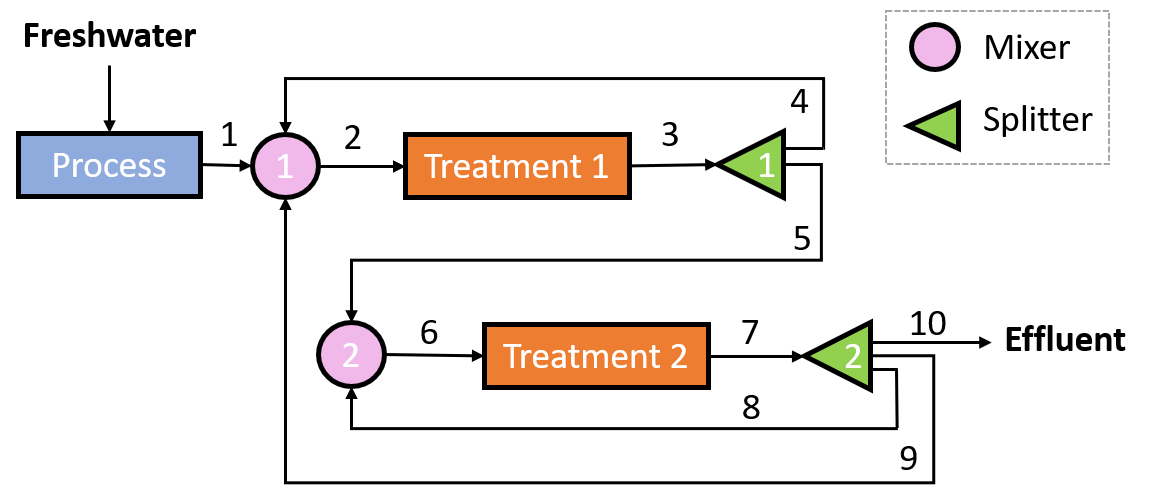

The flowrate of water required by each process unit, along with  containment inlet concentration limits, and amount of contaminant  discharged are given in Table 1. We'll assume an *𝛼* value of 0.7, an investment. The process unit uses 40 ton/h of freshwater and discharges 1 kg/h of A and 1kg/h of B.

The efficiency of the treatment units are given by the removal ratio in Table 2 along with cost model constants: 

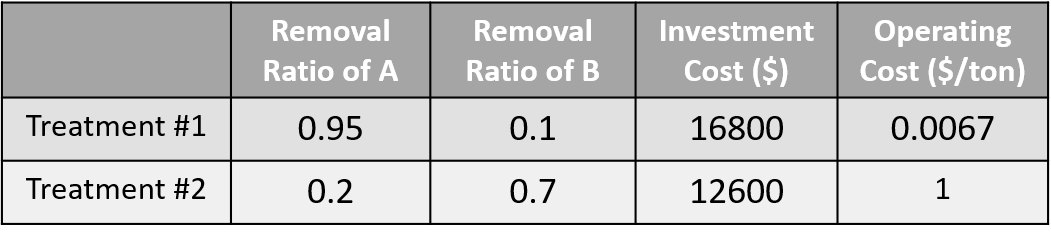

**INTERACTIVE!** Is this model convex or nonconvex? Continuous or mixed-integer? Why? 

We've now started to define objective and constraint functions which compute the concentration and flow rates assocaited with each stream and the overall system cost. Generally, there are two approaches to doing this. We can introduce a new variable for each concentration and flowrate and allow the optimizer to enforce mass balances. Alternative, we can algebraiclly re-arrange these mass balances and avoid introducing a large number of variables. In some cases, the former approach exposes special forms that an optimizer may use effectively. In other cases, the decreased number of variables may be more beneficial. We primarily use the later approach but we'll introduce variables to handle the recycle-loops which generally cannot be re-arranged into an explicit algebraic form. The optimization variables are $x=\left(F_{\mathrm{feed}} ,F_2 ,F_9 ,C_{A,4} ,C_{B,4} ,C_{A,9} ,C_{B,9} ,F_6 ,C_{A,8} ,C_{B,8} \right)$. Take some time to inspect the **constraint** function and reflect on the choice of these variables.

**Comment:** Generally optimizers require that all variables have both lower (lb) and upper (ub) bounds defined. If there aren't any obvious choices in a problem, you may have to exercise your best judgement and choose reasonable bounds. Equipment based bounds on flowrate are provided below. Further, we assume 0.1 is a sufficiently high concetration such that it will be an inactive constraint. Furthermore, an initial guess (x0) often must be specified. For convex problems, the solution obtained will generally not depend on this guess. 

% Bounds
lb = [0.1; 0.1; 0.1; 0.0; 0.0; 0.0; 0.0; 0.1; 0.0; 0.0];
ub = [100.0; 100.0; 100.0; 0.1; 0.1; 0.1; 0.1; 100.0; 0.1; 0.1];

% Specify initial guess
x0 = 0.5*(lb + ub);

**INTERACTIVE!: **Finish the intermediate calculations and constraints used in **constraints** functions at the end of the file. Follow the convention that f3 is the flowrate for stream 3, c1_2 is the concentration of species A in stream 2, and c2_3 is the concentration of species B in stream 3.  

Now, we solve the optimization problem.

% Solve optimization problem
options = optimoptions(@fmincon,'Algorithm','sqp');
[xopt,fval,flag,output,lambda] = fmincon(@(x)objective(x),x0,[],[],[],[],lb,ub,@(x)constraints(x),options);


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**INTERACTIVE!** Next we extract information about the optimization  problem. We'll want to check the status of the solve and the objective value, initially. Generally, optimizers will return codes to indicate if the solve was successful and to indicate any potential numerical issues that occur. Now, check the optimal solution and describe the system configuration.

In some cases, manufacturing plants are permitted a certain allowable amount of emissions at a particular site. Multiple emission sources may exist on a single site and it can be valuable to understand how expensive it is to reduce emissions in each process unit on that site. Let's determine the profitability associated with potentially relaxing our emissions target for this process. In order to do this, we'll perform a **sensitivity analysis**. That is to say, how much will changing a constraint and/or the variable bounds result in changing the solution? If we can perturb a constraint without affect this solution then the constraint is inactive. Otherwise, the dual values indicate the degree to which the solution may change by altering a constraint. We can obtain this information from the **lambda** structure. Nonlinear inequality constraint dual values are accessed via as shown below:

lambda.ineqnonlin

Optimizer exit flag = 1 


Objective value exit flag = 6790.294037 


Additional feed water used: = 0.100000 


Flowrate through treatment #1: = 5.783018 


Flowrate through treatment #2: = 0.100000 


**INTERACTIVE!** How much effect would changing the 10ppm effluent specification slightly have on the process cost?  

**INTERACTIVE!** Based on the form of the optimization problem, would you expect a local (convex) optimizer to return the best possible objective value? Why or why (not)? What sort of numerical experiments  would support a determination in either case?      

## A question to reflect on

We've solved two optimization problems: an integer program and a  nonlinear program. The full design of a wastewater treatment plant may  be handled by combining these two approaches. This can include which  process units, how many process units, and treatment units are included  as well as a full exploration of recycle loop configurations. This  variety of problem is termed [**superstructure optimization**](https://www.sciencedirect.com/science/article/abs/pii/S0098135405002991) and developing efficient means of solving these problems remains an active area of research. **How might we modify the above problem using 0-1 integer variables to explore other potential recycle configurations?**

**All the functions used within the above code are defined below:**

The objective function is defined as:

function Phi = objective(x)

ans = 	1.0e+08 *

    5.4839
         0


% financial assumptions
AR = 0.1;       % annualized factor
H = 8000;       % total hours plant operates
alpha = 0.7;    % scaling term for capital cost
Cwater = 1.0;   % cost of freshwater ($/ton)

% investment cost
Cinv1 = 16800.0;
Cinv2 = 12600.0;

% marginal operating cost
Cop1 = 0.0067;
Cop2 = 1;

% unpack variables
f1 = x(1);
f2 = x(2);
f3 = x(8);

% objective function
Phi = AR*(Cinv1*f2^alpha + Cinv2*f3^alpha) + Cop1*f2 + Cop2*f3 + H*f1*Cwater;
end

The constraints are defined as:

function [c,ceq] = constraints(x)

% process unit #1 (done)
Lp11 = 1.5/1000;
Lp21 = 1/1000;
f_feed = x(1);
f1 = 40 + f_feed;
c1_1 = Lp11/f1;
c2_1 = Lp21/f1;

% mixer #1
f2 = x(2);
f9 = x(3);
c1_4 = x(4);
c2_4 = x(5);
c1_9 = x(6);
c2_9 = x(7);

f4 = f2 - f1 - f9; 
c1_2 = (c1_1*f1 + c1_4*f4 + c1_9*f9)/f2;
c2_2 = (c2_1*f1 + c1_4*f4 + c2_9*f9)/f2;

% treatment unit #1  (TO COMPLETE)
removal_rate1_1 = 1.0 - 0.95;
removal_rate1_2 = 1.0 - 0.2;

% splitter #1 (TO COMPLETE)

% mixer #2
f6 = x(8);
f8 = f6 - f5;
c1_8 = x(9);
c2_8 = x(10);
c1_6 = (c1_5*f5 + c1_8*f8)/f6;
c2_6 = (c2_5*f5 + c2_8*f8)/f6;

% treatment unit #2
removal_rate2_1 = 1.0 - 0.1;
removal_rate2_2 = 1.0 - 0.7;
f7 = f6;
c1_7 = removal_rate2_1*c1_6;
c2_7 = removal_rate2_2*c2_6;

% splitter #2
f10 = f7 - f8 - f9;
c1_10 = c1_7;
c2_10 = c2_7;
ceq(3) = c1_8 - c1_7;
ceq(4) = c2_8 - c2_7;
ceq(5) = c1_9 - c1_7;
ceq(6) = c2_9 - c2_7;

% inequality constraints
c1_spec = 0.00001;
c2_spec = 0.00001;
cons_1 = c1_10 - c1_spec;
cons_2 = c2_10 - c2_spec;

c = [cons_1; cons_2];
end